assert(endsWith(pwd, "\biological block in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

## Distributed Current Source

#### Electromagnet

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)

Coil_pos = [0, 0, 4e-3]; % (m)
Coil = SetPositionRotation3D(Coil, Coil_pos, [1,0,0], deg2rad(0));
clear Coil_pos

#### Sensor

Sensor.num = 11;
Sensor.side_length = 0.6e-3;

Sensor_pos = [
    linspace(-20e-3,20e-3,Sensor.num); 
    0    * ones(1,Sensor.num); 
    1.5e-3 * ones(1,Sensor.num)];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos');
clear Sensor_pos

#### Model

block.l = 40e-3; % (m)
block.h = 10e-3;  % (m)
block.n_l = 16; % number of elements in x and y direction
block.n_z = 4;  % number of elements in z direction

x = linspace(-block.l/2, block.l/2, block.n_l+1);
y = x;
z = linspace(-block.h, 0, block.n_z+1);

Model = BuildModel3D('Cuboid', x,y,z);

build model took 0.04 seconds


clear block x y z

f = 2e6; % (Hz)
Model.conductivity          = 0.22522904495669013 * ones(1,Model.num_elems); % (S/m)
Model.relative_permittivity = 823.9912684178425 * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);

build governing equation took 2.22 seconds


#### Solve in frequency domain

V_E = readmatrix('FEA_data/V_E.csv', 'CommentStyle','%');
V_E = V_E(4);
Coil.frequency_domain.excitation = {"Voltage" V_E}; % (V)
clear V_E

% Coil.frequency_domain.excitation = {"Current" 0.01}; % (A)

Coil.frequency_domain.frequency = f;
clear f

[Model, Coil, Sensor] = SolveFrequencyDomain3D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 1.12 seconds


#### Plot world

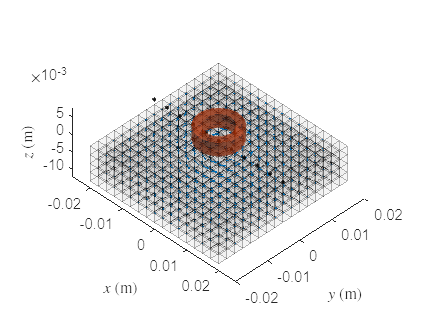

r = Model.elems_center;
J = real(Model.frequency_domain.J);

figure
PlotWorld3D(Model, Coil, Sensor);
quiver3(r(1,:),r(2,:),r(3,:), J (1,:),J (2,:),J (3,:));


clear r J

## Compare with FEA

#### Magnetic flux density

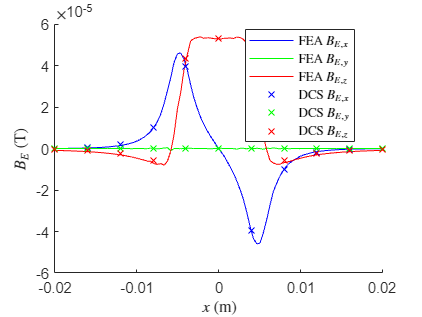

data = readmatrix('FEA_data/B.txt', 'CommentStyle','%');
FEA.x     = data(:,1);
FEA.B_E_x = data(:,7);
FEA.B_E_y = data(:,8);
FEA.B_E_z = data(:,9);
FEA.B_C_x = data(:,4) - FEA.B_E_x;
FEA.B_C_y = data(:,5) - FEA.B_E_y;
FEA.B_C_z = data(:,6) - FEA.B_E_z;
clear data

figure
hold on
plot(FEA.x, real(FEA.B_E_x), 'b-', 'DisplayName','FEA $B_{E,x}$')
plot(FEA.x, real(FEA.B_E_y), 'g-', 'DisplayName','FEA $B_{E,y}$')
plot(FEA.x, real(FEA.B_E_z), 'r-', 'DisplayName','FEA $B_{E,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(1,:)), 'bx', 'DisplayName','DCS $B_{E,x}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(2,:)), 'gx' ,'DisplayName','DCS $B_{E,y}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(3,:)), 'rx' ,'DisplayName','DCS $B_{E,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')

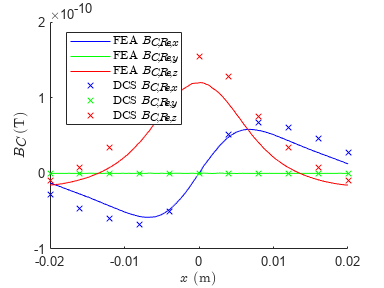


figure
hold on
plot(FEA.x, real(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Re,x}$')
plot(FEA.x, real(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Re,y}$')
plot(FEA.x, real(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Re,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,x}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,y}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Re,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')

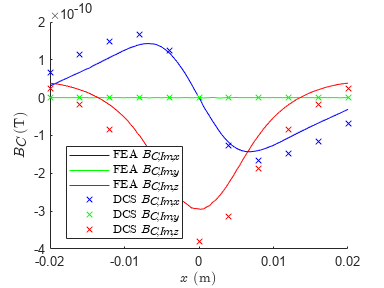


figure
hold on
plot(FEA.x, imag(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Im,x}$')
plot(FEA.x, imag(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Im,y}$')
plot(FEA.x, imag(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Im,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Im,x}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Im,y}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')